# ReLU Visualize

An interactive tool to visualize how ReLUs work in NNs. Using linear functions mx + c.

### Plot

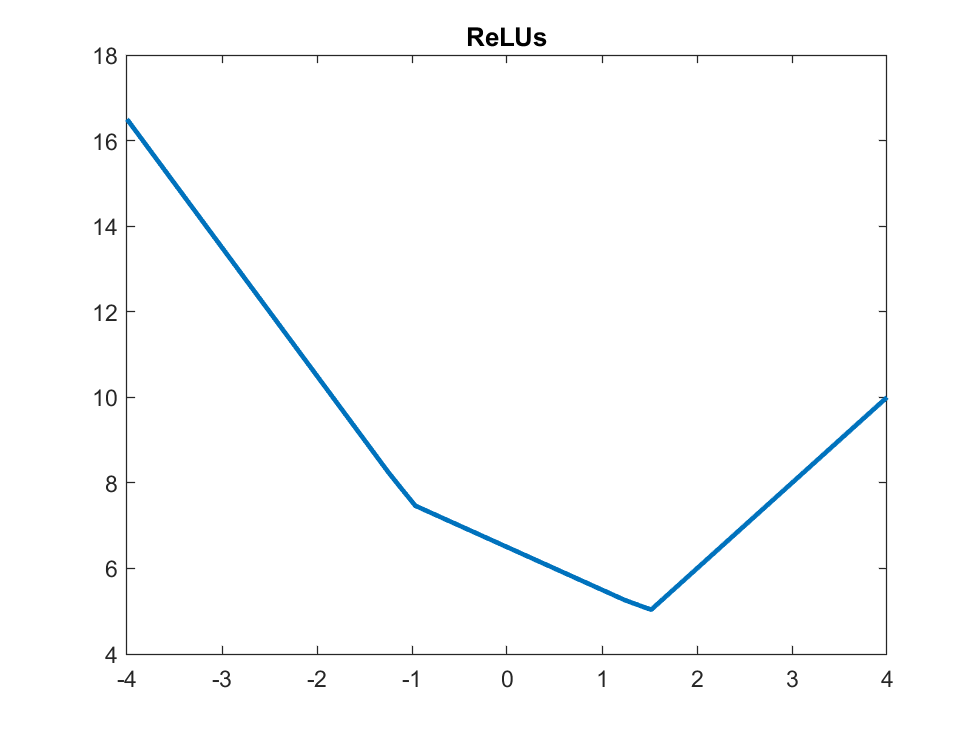

rangeVal = linspace(-4,4,30);

%First linera function
m1 = 2;
c1 = 2;
lin_func1 = m1.*rangeVal + c1;
relu1 = calc_relu(lin_func1);

%Second linera function
m2 = -3;
c2 = 4.5;
lin_func2 = m2.*rangeVal + c2;
relu2 = calc_relu(lin_func2);

plot_relus(rangeVal,relu1,relu2);

### Functions

function relu = calc_relu(lin_func)
    pos = find(lin_func <= 0);
    lin_func(pos) = 0;
    
    relu = lin_func;
end

function plot_relus(rangeVal, varargin)
    relu = 0;
    for i = 1:length(varargin)
        relu = relu + varargin{i};
    end
    plot(rangeVal,relu,'LineWidth',2);
    
    title("ReLUs");
    xlim([rangeVal(1) rangeVal(end)]);
end